# Ecuaciones diferenciales de orden superior

Resolver ecuaciones diferenciales de segundo orden:


$$y'' + 2y' + y = 0;$$
      
$$y(0) = 5,$$
      
$$y'(0) = -3;$$


syms y(t) t

dy = diff(y, t);
d2y = diff(y, t, 2);

y0 = 5;
dy0 = -3;

y(t) = dsolve(d2y == -2*dy - y ...
    , y(0) == y0 ...
    , dy(0) == dy0)

$$y(t) = {\mathrm{e}}^{-t}\,\left(2\,t+5\right)$$

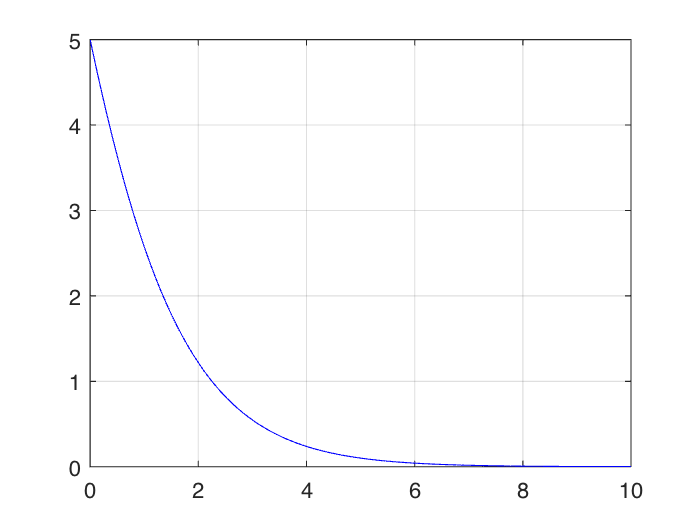


tt = linspace(0, 10);
yy = y(tt);

plot(tt, yy, 'b');
grid on;

También se puede modelar un sistema masa resorte amortiguado:


$$m\frac{d^2 }{\mathrm{d}t^2 }x+b\frac{d}{\mathrm{d}t}x+kx=f$$



$$\ddot{x} =\frac{1}{m}f-\frac{b}{m}\dot{x} -\frac{k}{m}x$$


syms x(t) t

f = t;
m = 0.5;
b = 0.01;
k = 0.05;
x0 = 0;
dx0 = 1;

dx = diff(x, t);
d2x = diff(x, t, 2);

x(t) = dsolve(d2x == (1/m)*f - (b/m)*dx - (k/m)*x ...
    , x(0) == x0 ...
    , dx(0) == dx0)

$$x(t) = 20\,t+4\,{\mathrm{e}}^{-\frac{t}{100}}\,\cos\left(\frac{3\,\sqrt{111}\,t}{100}\right)-\frac{632\,\sqrt{111}\,{\mathrm{e}}^{-\frac{t}{100}}\,\sin\left(\frac{3\,\sqrt{111}\,t}{100}\right)}{111}-4$$

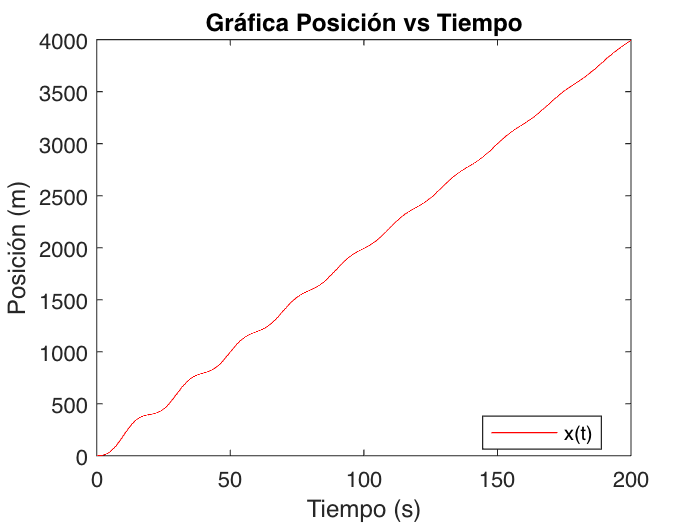


tt = linspace(0, 200, 2000);
xx = x(tt);

plot(tt, xx, 'r')
title('Gráfica Posición vs Tiempo')
legend('x(t)', 'Location', 'best')
xlabel('Tiempo (s)')
ylabel('Posición (m)')